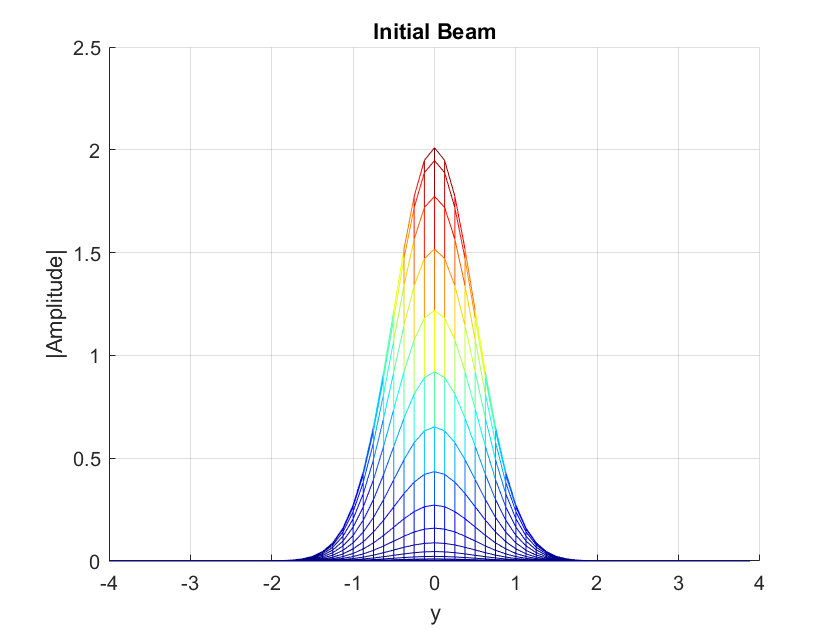

% Define the 2D spatial grid
x = linspace(-4, -4 + 63 * 8 / 64, 64);  % x-coordinates
y = linspace(-4, -4 + 63 * 8 / 64, 64);  % y-coordinates

% Step size and number of propagation steps
step_size_z = 1.0;  % Step size in z-direction
num_steps = 35;     % Number of propagation steps

% Initialize the 2D Gaussian beam with added noise
[X, Y] = meshgrid(x, y);  % Create a 2D grid
initial_beam = 2.01 * exp(-2 * X.^2) .* exp(-2 * Y.^2) + 0.000 * rand(64);

% Compute initial energy to verify numerical accuracy later
initial_energy = sum(sum(abs(initial_beam.^2)));

% Plot the initial beam
figure(1);
mesh(x, y, abs(initial_beam));
view(90, 0);
title('Initial Beam');
xlabel('x');
ylabel('y');
zlabel('|Amplitude|');

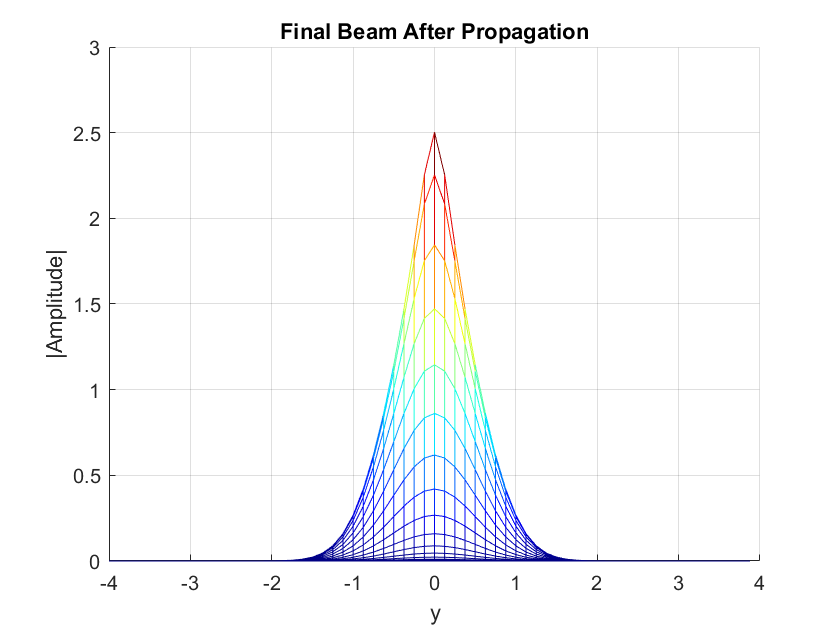


% Define the 2D spatial frequency grid
u = linspace(-1, -1 + 63 * 2 / 64, 64);  % u-coordinates
v = linspace(-1, -1 + 63 * 2 / 64, 64);  % v-coordinates

% Create the transfer function for beam propagation
[U, V] = meshgrid(u, v);
transfer_function = exp(1i * U.^2 * step_size_z * 0.05) .* exp(1i * V.^2 * step_size_z * 0.05);

% Apply FFT shift for proper alignment
propagation_filter = fftshift(transfer_function);

% Initialize the beam for propagation
current_beam = initial_beam;

% Split-step beam propagation method
for step = 1:num_steps
    % Transform to spatial frequency domain
    beam_spectrum = fft2(current_beam);
    
    % Apply the transfer function
    filtered_spectrum = beam_spectrum .* propagation_filter;
    
    % Transform back to spatial domain
    propagated_beam = ifft2(filtered_spectrum);
    
    % Compute intensity for the nonlinear phase modulation
    intensity = (propagated_beam .* conj(propagated_beam)) / 2.0;
    
    % Apply the nonlinear phase modulation
    nonlinear_phase = exp(-1i * intensity * 0.05);
    propagated_beam = propagated_beam .* nonlinear_phase;
    
    % Propagate once more
    beam_spectrum = fft2(propagated_beam);
    filtered_spectrum = beam_spectrum .* propagation_filter;
    propagated_beam = ifft2(filtered_spectrum);
    
    % Update the beam
    current_beam = propagated_beam;
end

% Plot the final beam
figure(2);
mesh(x, y, abs(current_beam));
view(90, 0);
title('Final Beam After Propagation');
xlabel('x');
ylabel('y');
zlabel('|Amplitude|');


% Compute the final energy to verify numerical accuracy
final_energy = sum(sum(abs(current_beam.^2)));

% Display energy results
fprintf('Initial Energy: %.4f\n', initial_energy);

Initial Energy: 203.0776


fprintf('Final Energy: %.4f\n', final_energy);

Final Energy: 203.0776
